clear 
clc
fs = 41.667e3

fs = 41667

freqList = linspace(0, 20.8e3-300, 42) % 0 til 20.5 kHz med 500 Hz hop

freqList =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000        5500        6000        6500        7000        7500        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       16500       17000       17500       18000       18500       19000       19500       20000       20500


freqList(1) = 50;
%micList = 0:6
micList = ones(1, 7)*3

micList =      3     3     3     3     3     3     3


mic3Power = zeros(length(micList),length(freqList));
degList = (1:5:180) - 1

degList =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175


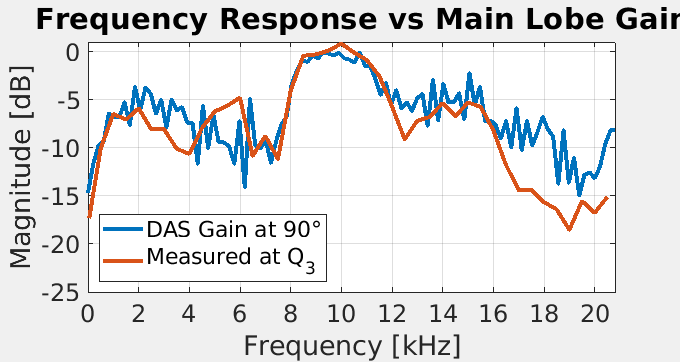

numSamples = 190;
numMics = 8;

gains = zeros(7,3);
dcOffset = zeros(7,3);
numTries = 3;
for f = 1:length(freqList)
    for t = 1:numTries
        fileID = fopen('degree_' + string(90) ...
            + '_freq_' + string(freqList(f)) + '_num_' + string(t-1));
        data = fread(fileID,'single');  
            data = data/(power(2,31)-1);
            numMics = 8;
            numSamples = 190;
            onePacketLength = numSamples*numMics;
            numPacketsInData = floor(length(data)/onePacketLength);
            for m = 1:7
            %for m = 4:4
                for i = 0:numPacketsInData-1
                   mic3Power(m,f) = mic3Power(m,f) + mean(data(1+(micList(m)*numSamples)+i*onePacketLength: ... 
                           (micList(m)*numSamples)+i*onePacketLength+numSamples).^2);
                end
            end
            mic3Power(m,f) = mic3Power(m,f)/numTries;
    end
end
meanMicPower = mean(mic3Power);
meanMicPower(end-1) = (meanMicPower(end-3)+meanMicPower(end-2))/2;

load("gainAtSteeringESS90.mat")

set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 12])
%plot(outputFreq(1,:),outputdB(indexDeg,:), 'LineWidth', 4)
plot(gainFreq,gainGain, 'LineWidth',3)
hold on
plot(freqList,pow2db(meanMicPower)+3, 'LineWidth',3)
ylim([-25 1])
xlim([0 20.8e3])
ytickList = linspace(-25,0,5+1);
yticks(ytickList(1:1:end))
yticklabels(string(ytickList(1:1:end)))
%xtickList = linspace(0,20.8e3,20.8e3/1000+1);
xtickList = linspace(0,21e3,22);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
title('  Frequency Response vs Main Lobe Gain', 'FontSize', 22)
legend('DAS Gain at 90°', 'Measured at Q_3', 'Location', 'southwest')
grid
hold off
exportgraphics(gcf,'FreqRespVSMainGain.pdf')



%freqAdjustment = sqrt(max(mic3Power')'./mic3Power)
%plot(freqList,freqAdjustment)